2.3

a)

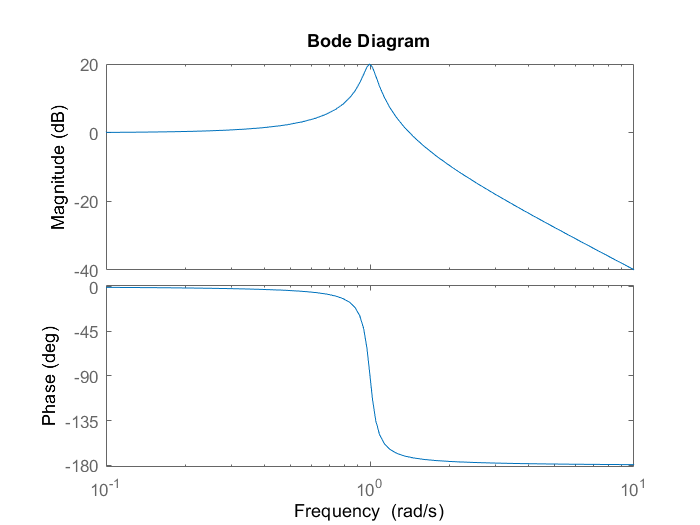

num31=(1);
csei31=[0.1 0.3 0.7];
s=0:0.001:20;
for i=1:3
den31(i,:)=[1 csei31(i) 1];
end
bode(num31,den31(1,:));

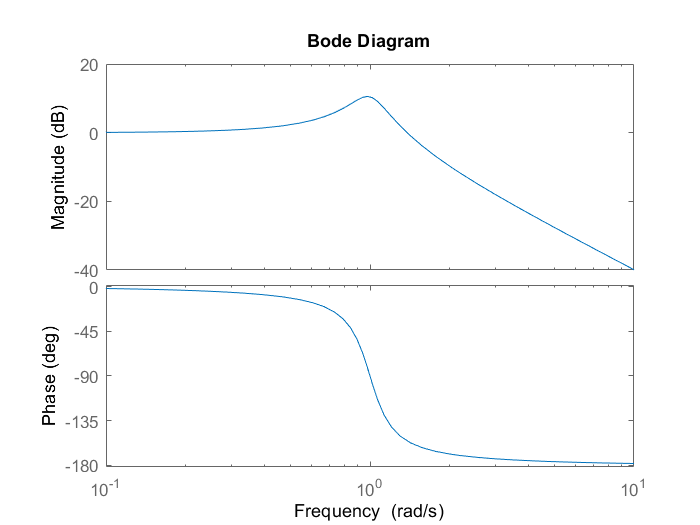

bode(num31,den31(2,:));

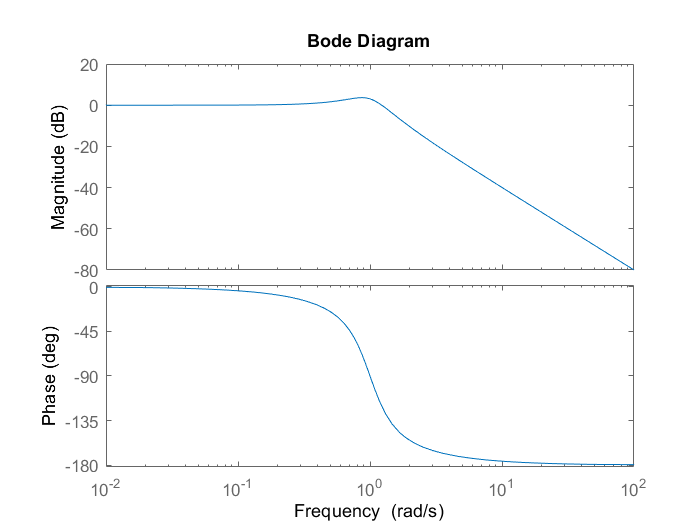

bode(num31,den31(3,:));

b)

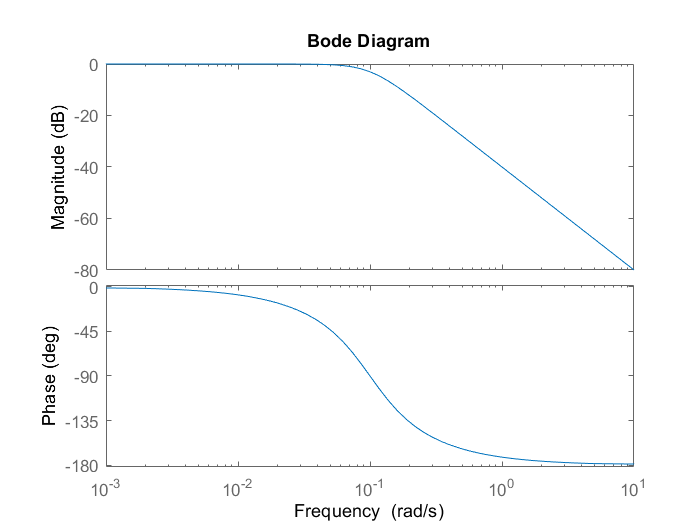

wn=[0.1,0.3,0.7];
csei=0.707;
s=0:0.001:20;
for i=1:3
den32(i,:)=[1 2*csei*wn(i) wn(i)^2];
end
bode(wn(1)^2,den32(1,:));

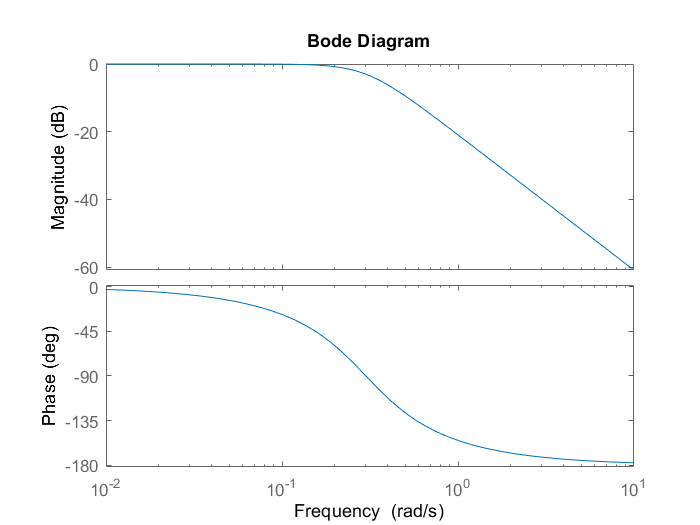

bode(wn(2)^2,den32(2,:));

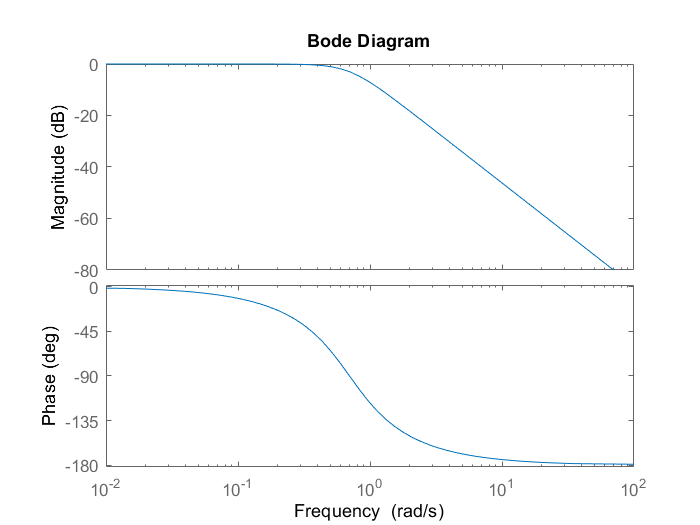

bode(wn(3)^2,den32(3,:));

datestr(now,21)

ans = 'Mar.26,2021 20:30:00'

2.5

num=100*conv([1 5],[1 5]);
den=conv([1 1],[1 1 9]);
G_k=tf(num,den)

G_k =
 
  100 s^2 + 1000 s + 2500
  -----------------------
  s^3 + 2 s^2 + 10 s + 9
 
Continuous-time transfer function.



G_c=feedback(G_k,1);
[Gm,Pm,Wcg,Wcp]=margin(G_k)

Gm = Inf

Pm = 85.4365

Wcg = NaN

Wcp = 100.3285

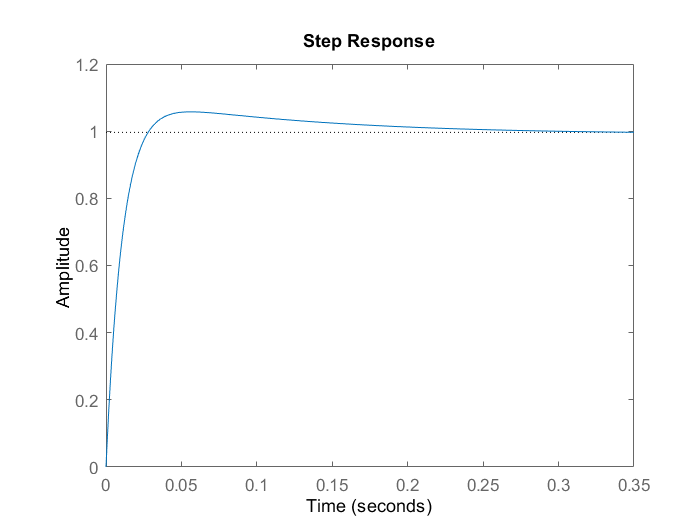

step(G_c)

datestr(now,21)

ans = 'Mar.26,2021 20:30:02'